clear all
syms s
G=((6*s*(s+0.5)/((s^2+2*s+10)*(s+1))));
ANS=simplify(G)

$$ANS = \frac{6\,s\,\left(s+\frac{1}{2}\right)}{\left(s+1\right)\,\left(s^{2}+2\,s+10\right)}$$

[n,d]=numden(ANS)

$$n = 3\,s\,\left(2\,s+1\right)$$

$$d = \left(s+1\right)\,\left(s^{2}+2\,s+10\right)$$


num=double(coeffs(n,'All'))

num =      6     3     0


den=double(coeffs(d,'All'))

den =      1     3    12    10


H=tf(num,den)

H =
 
        6 s^2 + 3 s
  -----------------------
  s^3 + 3 s^2 + 12 s + 10
 
Continuous-time transfer function.



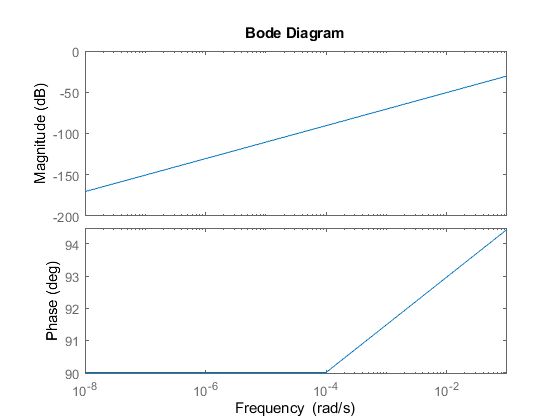

%bode_asymptotic(H,foptions)
bode(H,foptions)

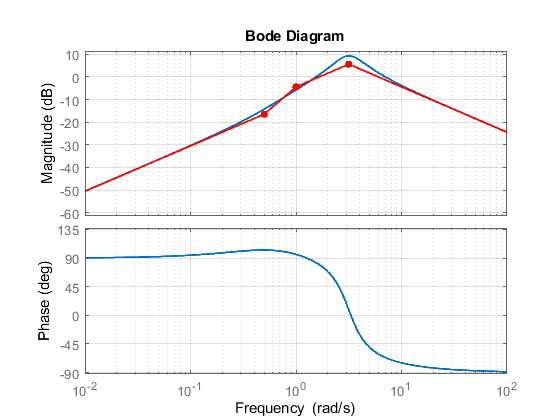


asymp(H)
grid on 

fidgs

function asymp(sys,wlow,whigh);
% The function asymp() corresponds to bode(), 
% but it also plots asymptotes for the magnitude 
% and phase graphs. Phase asymptotes are vertical. 
% asymp() only accepts monovariable transfer functions.
% 
% If the transfer function also has a time delay, the time delay is ignored
% for the phase asymptotes.
% 
% asymp() may be called in two ways only, asymp(h), 
% or asymp(h,wmin,wmax). 
if nargin == 3           
    bode(sys,{wlow,whigh});
elseif nargin == 1
    bode(sys);
else
    error('arguments must be either ''h'' -- or ''h,wmin,wmax''');
end
hold on;
           
[num,den] = tfdata(sys,'v');
if nargin == 3           
    [mag,phase,w] = bode(sys,{wlow,whigh});
elseif nargin == 1
    [mag,phase,w] = bode(sys);
end
% Refining the w vector, so that we get 10 times 
% as many w points as that used by bode() by default:
w=logspace(log10(w(1)),log10(w(end)),10*length(w));
[mag,phase] = bode(sys,w);
mag=20.*log10(squeeze(mag));
phase=squeeze(phase);
% if max(phase) > 170 & mean(phase) > 60
%     phase =phase-360; 
%     % bode( ) sometimes shifts a phase plot +360 degrees in a misleading way, so 
%     % this is an attempt to rectify this. But the criteria are admittedly a bit arbitrary ;-)
% end
plot(w,phase,'LineWidth',1.5);
% Order of denominator polynomial and
% number of pure integrators, if any, are found:
dendeg = length(den)-1;
k= dendeg+1;
while den(k) == 0 k=k-1; end
% Number of pure integrators, if any:
denintegr = dendeg+1-k;
% Order of denominator, and denominator itself, 
% that remains when integrators are ignored:
den=den(1:dendeg+1-denintegr);
dendeg=k-1;
% Removing possible higher order term zero 
% coefficients in nominator:
k=1;
while num(k) == 0 k=k+1; end
numdeg= length(num)-k;
num=num(k:k+numdeg);
% Order of remaining nominator polynomial, and
% number of pure derivators, if any, are found:
k= numdeg+1;
while num(k) == 0 k=k-1; end
numderiv = numdeg+1-k;
num=num(1:numdeg+1-numderiv);
numdeg=k-1;
% Total zero frequency gain ignoring
% integrators and derivators:
gain = num(length(num))/den(length(den)); 
% Negative gain, if any, is accounted for:
gainneg = gain < 0; gain=abs(gain);
% Finding left start points for amplitude and phase:
magstart= 20*log10(gain/w(1)^(denintegr-numderiv));
phastart=90*round(phase(1)/90);
% initial slope for magnitude:
magslopeaccum=-20*(denintegr-numderiv);
% Roots of remaining numerator and denominator:
zeroes=roots(num);
poles=roots(den);
% Putting all roots in one long row vector with zeroes first:
zerpoles=[zeroes',poles'];
% All changes in magnitude and 
% phase are found and stored in vectors 
% dmag and dph corresponding to zerpoles:
%
% Finding change in magnitude and phase due to each zero, if any:
if numdeg > 0
    dmag(1:numdeg)= 20*ones(1,numdeg);
    dph(1:numdeg)= 90*(round(2*((real(zeroes) < 0)-0.5)));
end
% Finding change in magnitude and phase due to each pole, if any:
dmag(numdeg+1:numdeg+dendeg)= -20*ones(1,dendeg);
dph(numdeg+1:numdeg+dendeg)= 90*(round(2*((real(poles) > 0)-0.5)));
% Finding break frequencies. They are sorted, but we keep
% track of original order of zerpoles, dmag and dph,
% A trick is employed to ensure sorting based on absolute value,
% even if poles may all be real:
[freqpoints,ord] = sort(abs(complex(real(zerpoles),imag(zerpoles))));
% adding first and last frequency point for plot:
freqpoints=[w(1),freqpoints,w(end)];
np=length(freqpoints);
% Allocating vectors for mag and phase plots.
% Phase points are many since the asymptote is vertical at each 
% break point and therefore two points are needed per break point:
magpoints=ones(1,np); 
phapoints=ones(1,2*(np-1));
% Initial points that are to be plotted later:
magpoints(1)= magstart;
phapoints(1)= phastart; phapoints(2)= phastart;
% Finding remaining points for mag and phase plots:
for k = 2:np
    if k > 2 
%       Accumulated slope is updated:        
        magslopeaccum=magslopeaccum+dmag(ord(k-2)); 
    end
%   Magnitude points are calculated:    
    magpoints(k)= magpoints(k-1)+ magslopeaccum*log10(freqpoints(k)/freqpoints(k-1));
%   Phase points are calculated:    
    if k < np
        phapoints(2*k-1)= phapoints(2*k-2)+dph(ord(k-1));
        phapoints(2*k)= phapoints(2*k-1);
    end
end
% Make the magintude axes current, and plot there:
h=get(findall(get(gcf,'Children'),'String','Magnitude (dB)'),'Parent');
axes(h);
yxlim=axis;
hold on;
grid;
plot(w,mag,'LineWidth',1.5);
magmax=max([magpoints,mag']); magmin=min([magpoints,mag']);
yspan = magmax-magmin;
for ydelta = [2 4 10 20 40]
    yhlp = yspan/ydelta;
    if yhlp < 8 
        break; 
    end
end
magmin=ydelta*floor(magmin/ydelta); magmax=ydelta*ceil(magmax/ydelta);
if magmin == magmax 
    magmin = magmin-2; magmax=magmax+2;
end
maglimitincr=(magmax-magmin)*0.02;
set(get(gcf, 'CurrentAxes'),'YTick',magmin:ydelta:magmax);
set(get(gcf, 'CurrentAxes'),'YLim',[magmin magmax]);
yscalemag = axis;
yscalemag(3) = magmin-maglimitincr; yscalemag(4) = magmax+maglimitincr;
axis(yscalemag);
% Magnitude asymptote plot on top of magnitude part of Bode diagram:
plot(freqpoints(2:np-1),magpoints(2:np-1),'r.-','MarkerSize',14,'LineWidth',1.3);
% No dots at start and end points:
plot(freqpoints(1:2),magpoints(1:2),'r-','LineWidth',1.3);
plot(freqpoints(np-1:np),magpoints(np-1:np),'r-','LineWidth',1.3);
hold off;
% Phase asymptote plot on top of phase part of Bode diagram. 
% First make the phase axes current, and plot grid:
h=get(findall(get(gcf,'Children'),'String','Phase (deg)'),'Parent');
axes(h);
hold on;
grid;
% Phase asymptotes may exceed current upper and lower limit
% values in phase diagram. Find max and min phase asymptote
% values, and re-scale phase diagram:
phmax=max([phapoints,phase']); phmin=min([phapoints,phase']);
yspan = phmax-phmin;
for ydelta = [10 15 30 45 90 180]
    yhlp = yspan/ydelta;
    if yhlp < 8 
        break; 
    end
end
phmin=ydelta*floor(phmin/ydelta); phmax=ydelta*ceil(phmax/ydelta);
if phmin == phmax 
    phmin = phmin-45; phmax=phmax+45;
end
end